# H2

I = double(imread("rabbit.jpg"));
imshow(I);

## Filtre laplacià

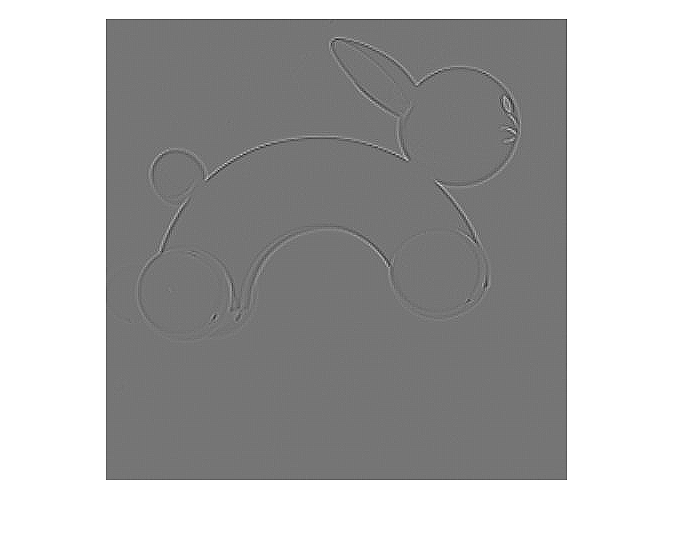

hL = [0 1 0; 1 -4 1; 0 1 0];
L = imfilter(double(I), hL);
imshow(L, []); 

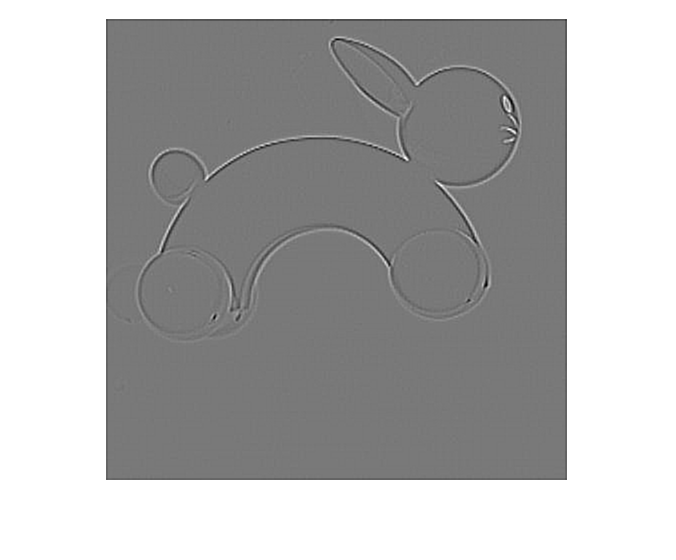


% Millores:
% Amb una Laplaciana of Gaussian, filtrem i 
% apliquem Laplaciana, Tot en un. 

hLoG = fspecial('log',5,1);
LoG = imfilter(I,hLoG);
imshow(LoG,[])

## Detecció passos per zero

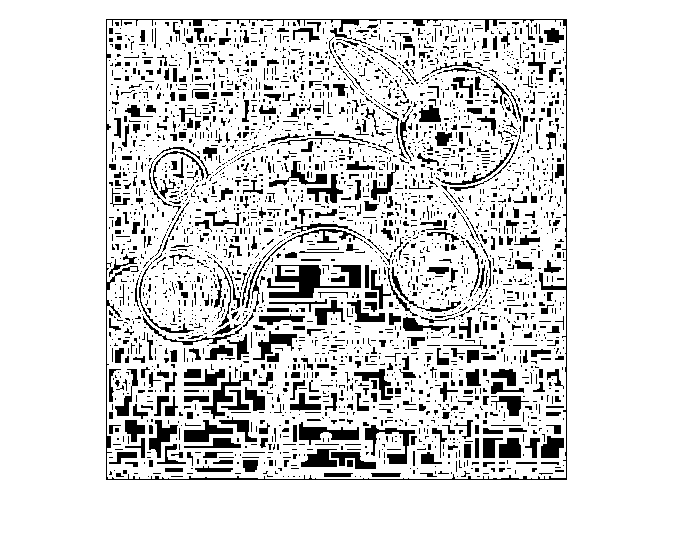

% Es busca que la Laplaciana passi per zero . 
% Es a dir aquells pixels en que tingui un vei sigui positiu i algun vei
% negatiu

P = LoG > 0; % pixels amb valor positiu
N = LoG < 0; % pixels amb valor negatiu


SP = colfilt(P,[3 3],"sliding",@sum); % fa la suma dels veis positius
SN = colfilt(N,[3 3],"sliding",@sum); % fa la suma dels veis negatius
% Nota: la funció colfilt ens proporciona els veins de cada pixel i després aplica la funcio que li passem com a parametre 

UP = SP > 0; % almenys un vei positiu
UN = SN > 0; % almenys un vei negatiu

Z = UP & UN;
imshow(Z);

## Imatge del contorn massa sorollosa

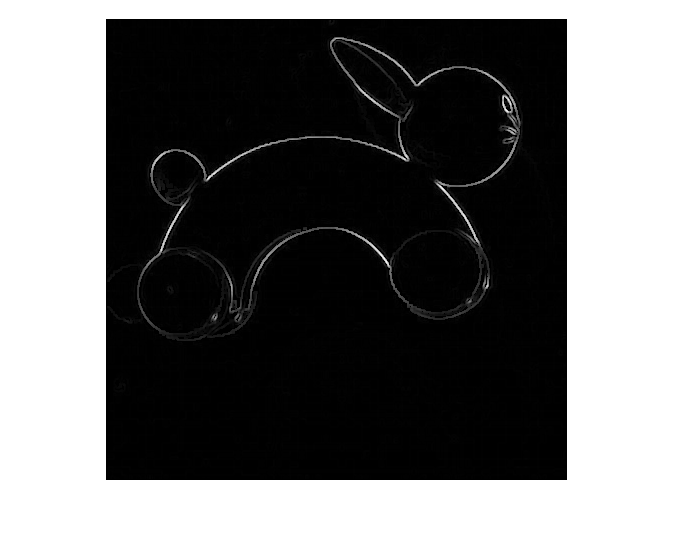

% Que el mòdul de la primera derivada sigui gran
% Calcul del modul de la primera derivada per Sobel
hx = [-1 0 1; -2 0 2; -1 0 1];
hy = -(hx');
Gx = imfilter(I, hx);
Gy = imfilter(I, hy);
G = abs(Gx) + abs(Gy); % modul del gradient (dx,dy)

R = Z .* G; % Enaltim els pixels de pass per zero amb el modul del gradient
imshow(R,[]);